clear all
clc
close all

load('dataForLearning.mat') 
graph.drawGraph(1);
graph.loadNeighbors();

#### Generating data 

% Agent,
agentId = 1;
% RHCP
RHCPId = 1;
numOfTargets = length(graph.targets);

collectedInputMatrix = cell(1,numOfTargets);
collectedOutputMatrix = cell(1,numOfTargets);
dataCountMatrix = zeros(1,numOfTargets);

for dataBlock = graph.agents(agentId).pastData
    dataBlock = cell2mat(dataBlock);
    if RHCPId==1 & size(dataBlock,2)==4 % (RHCPId==2 & size(dataBlock,2)==3) 
        i = dataBlock(1,1);
        jStar = dataBlock(1,size(dataBlock,2));
        if i == jStar
            continue;
        end
        
        u_iVals = dataBlock(:,3);
        u_iStar = u_iVals(dataBlock(:,1)==jStar);
        
        % output
        output = u_iStar;
        collectedOutputMatrix{i} = [collectedOutputMatrix{i}, output];
        
        % input
        input = zeros(length(graph.neighbors{i}),1);
        for jId = 1:1:size(dataBlock,1)
            j = dataBlock(jId,1);
            neighborIndex = find(graph.neighbors{i}==j);
            
            Omega_j = dataBlock(jId,2);
            input(neighborIndex) = Omega_j;
        end
        collectedInputMatrix{i} = [collectedInputMatrix{i}, input];
        
        dataCountMatrix(1,i) = dataCountMatrix(1,i) + 1; 
    end
end
dataCountMatrix

dataCountMatrix =     59    21    26    22    32    27    15    26    36    10


% Solve an Input-Output Fitting problem with a Neural Network
% Script generated by NFTOOL
%
% This script assumes these variables are defined:
%
%   houseInputs - input data.
%   houseTargets - target data.
targetId = 1;

inputs = collectedInputMatrix{targetId};
targets = collectedOutputMatrix{targetId};
 
% Create a Fitting Network
hiddenLayerSize = 10;
net = fitnet(hiddenLayerSize);

% Set up Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
 
% Train the Network
[net,tr] = train(net,inputs,targets);
 
% Test the Network
outputs = net(inputs);
errors = gsubtract(outputs,targets);
performance = perform(net,targets,outputs)

performance = 9.7758e-04

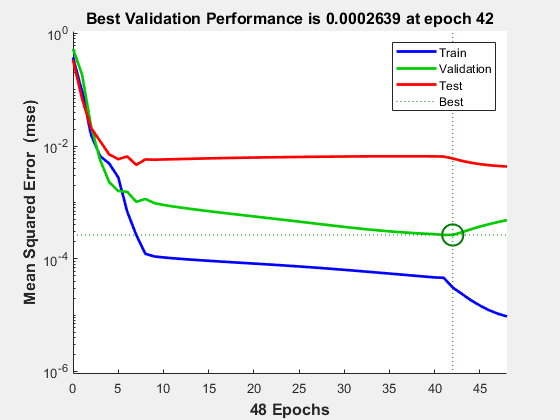

 
% View the Network
view(net)
 
% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)

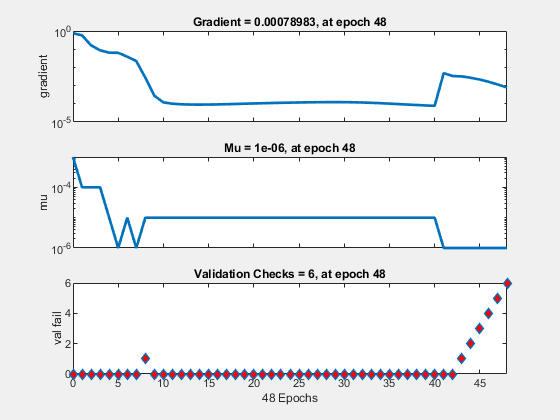

figure, plottrainstate(tr)

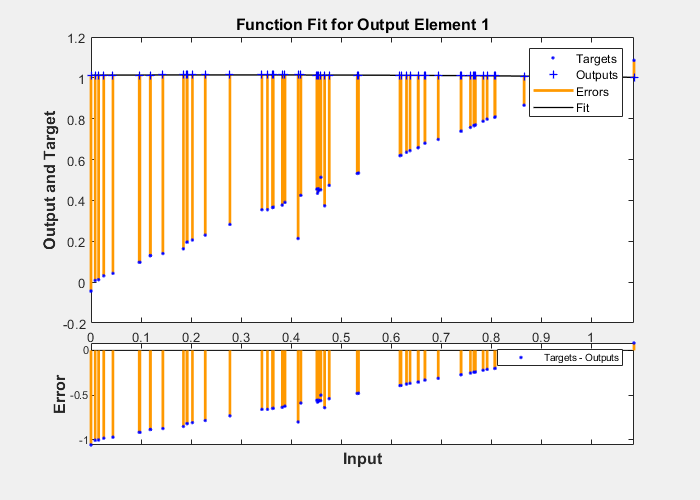

figure, plotfit(net,targets,outputs)

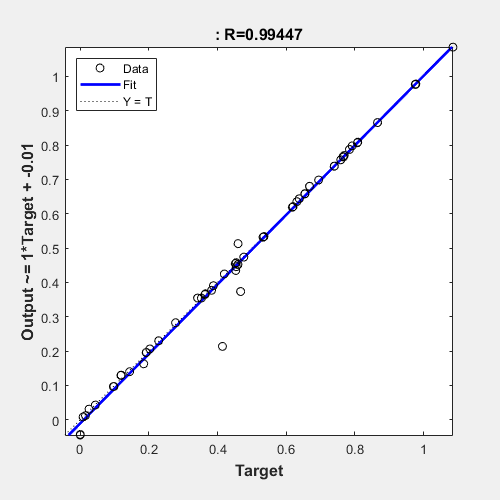

figure, plotregression(targets,outputs)

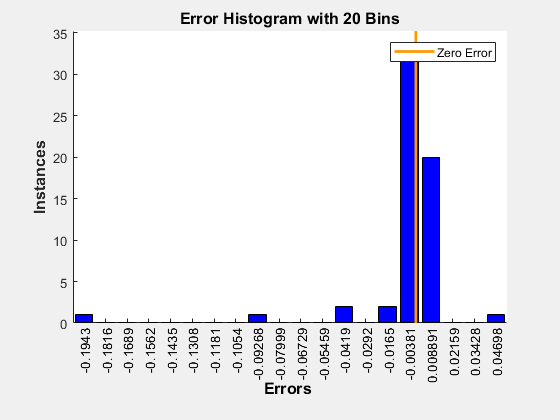

figure, ploterrhist(errors)